clc
clear all

## Part 1: Chromo Modal Dispersion

**Constants: **

c = 3*10^8; 
n = 1.5 % refractive index of the glass used in part 1

n = 1.5000

L = 20; % Length of cavity is 20 m

**a) **

We first must 'read-in' the data from the group delay file.  Wavelength is converted to angular frequency, which the group delay is plotted against.  Utilizing the polynomial fitting function, the phase per unit length coefficients can be obtained from this function of $\tau \;$vs $\omega$: $\tau \left(\omega \right)=\beta_1 +\beta_2 \left(\omega -\omega_0 \right)+\frac{\beta_3 }{2}{\left(\omega -\omega_0 \right)}^2$.  $\beta_0 \;$is the phase/unit length at the center wavelength, given by: $\beta_0 =2\pi \frac{n}{\lambda_0 }=n\frac{\omega }{c}$ for a constant refractive index n (1.5 in this case)

tauvslambda = readmatrix('CMD_Group_Delay.xlsx')

tauvslambda = 	1.0e+03 *

    1.5499   -0.0001
    1.5499    0.0003
    1.5499    0.0017
    1.5500    0.0024
    1.5500    0.0071
    1.5500    0.0088
    1.5500    0.0121
    1.5500    0.0121
    1.5501    0.0131
    1.5501    0.0145


tau_sweep = tauvslambda(:,2)*10^-12; % import group delay (ns to s)
lambda_sweep = tauvslambda(:,1)*10^-9; % import wavelength (nm to m)
% Condition variables for better polynomial fit, using mean and std. dev.
tau_mean = mean(tau_sweep);
tau_new = (tau_sweep-tau_mean); %./std(tau_sweep);
lambda_mean = mean(lambda_sweep);
%lambda0 = 1510*10^-9;
lambda_new = (lambda_sweep-lambda_mean); %./std(lambda_sweep);
omega_sweep = 2*pi*c./lambda_sweep;
%freq = linspace(min(omega_sweep./(2*pi)),max(omega_sweep./(2*pi)))
omega_mean = mean(omega_sweep);
omega_new = (omega_sweep-omega_mean); %./std(omega_sweep)
%beta_omega = n*omega_sweep./c; % group delay converted to phase
%plot(omega_new,tau_new)
coeff = polyfit(omega_new,tau_new,3)

coeff = 	1.0e+-10 *

    0.0000   -0.0000   -0.0000    0.1138


beta_0 = 2*pi*n/lambda_mean

beta_0 = 6.0796e+06

beta_1 = coeff(4)

beta_1 = 1.1378e-11

beta_2 = coeff(3)

beta_2 = -4.7567e-23

beta_3 = coeff(2)*2

beta_3 = -9.6088e-34

**b) **

Given this information, the dispersion coefficient, $D=\frac{d\tau }{d\lambda }=\frac{{d\beta }_1 }{d\lambda }=-\frac{2\pi c}{\lambda^2 }\beta_2 =-\frac{\lambda }{c}\frac{d^2 n}{d\lambda^2 }$

D = -(beta_2*10^6)*2*pi*c/(lambda_mean^2)

D = 3.7309e+04

**c)**

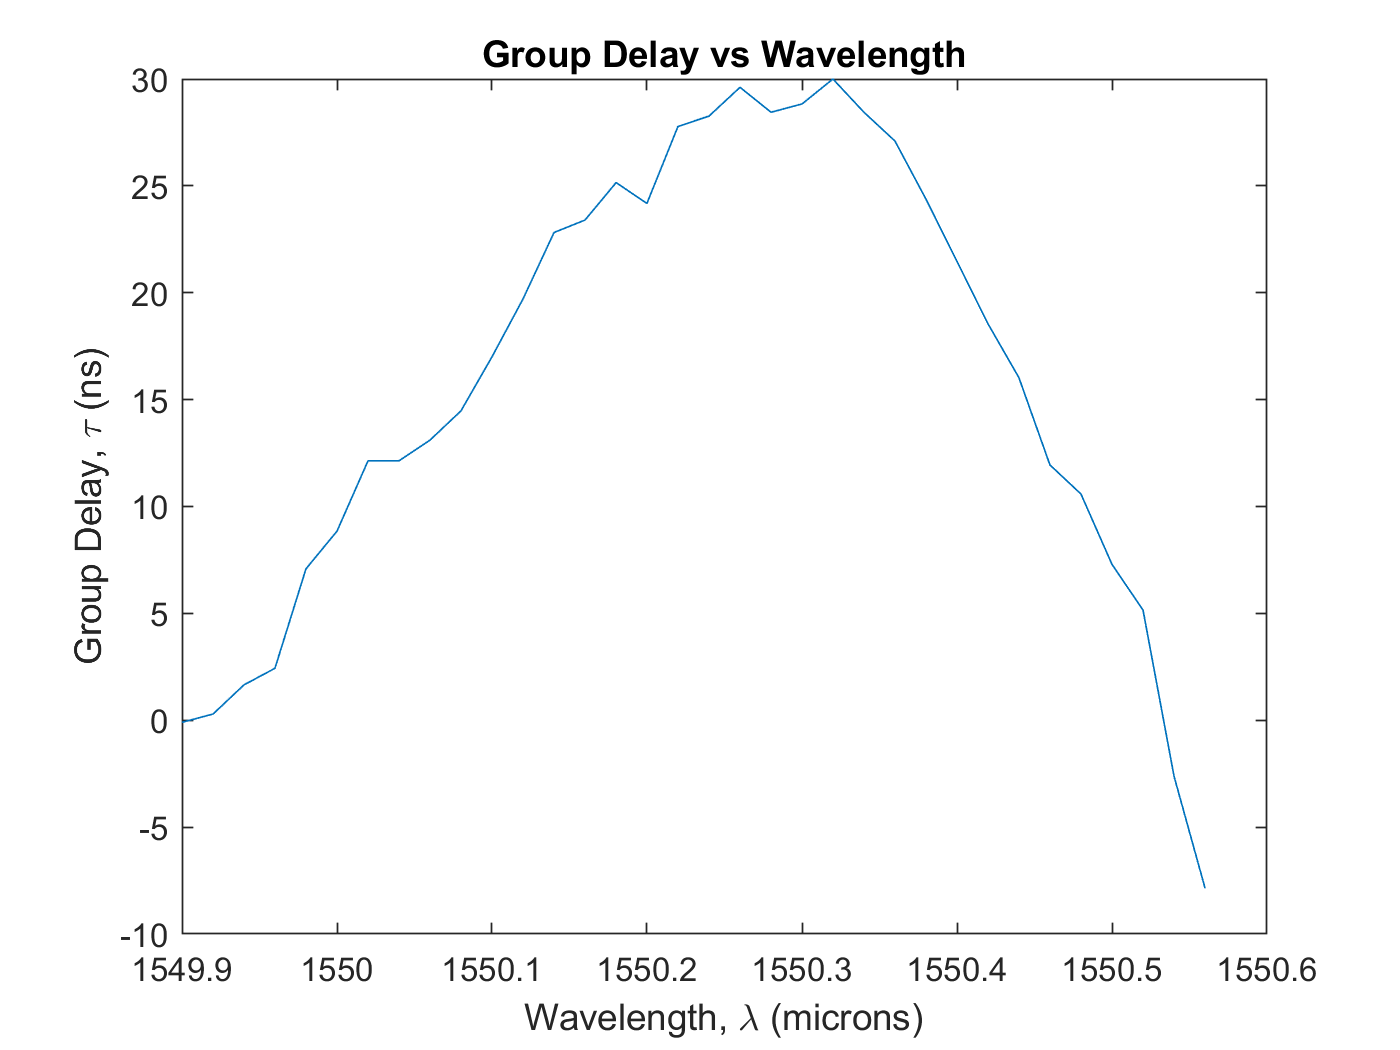

plot(lambda_sweep*10^9,tau_sweep*10^12)
xlabel('Wavelength, \lambda (microns)')
ylabel('Group Delay, \tau (ns)')
title('Group Delay vs Wavelength')

% Using polynomial fit determined previously
x = linspace(min(lambda_sweep), max(lambda_sweep));
coeffnew = polyfit(lambda_sweep,tau_sweep,3);

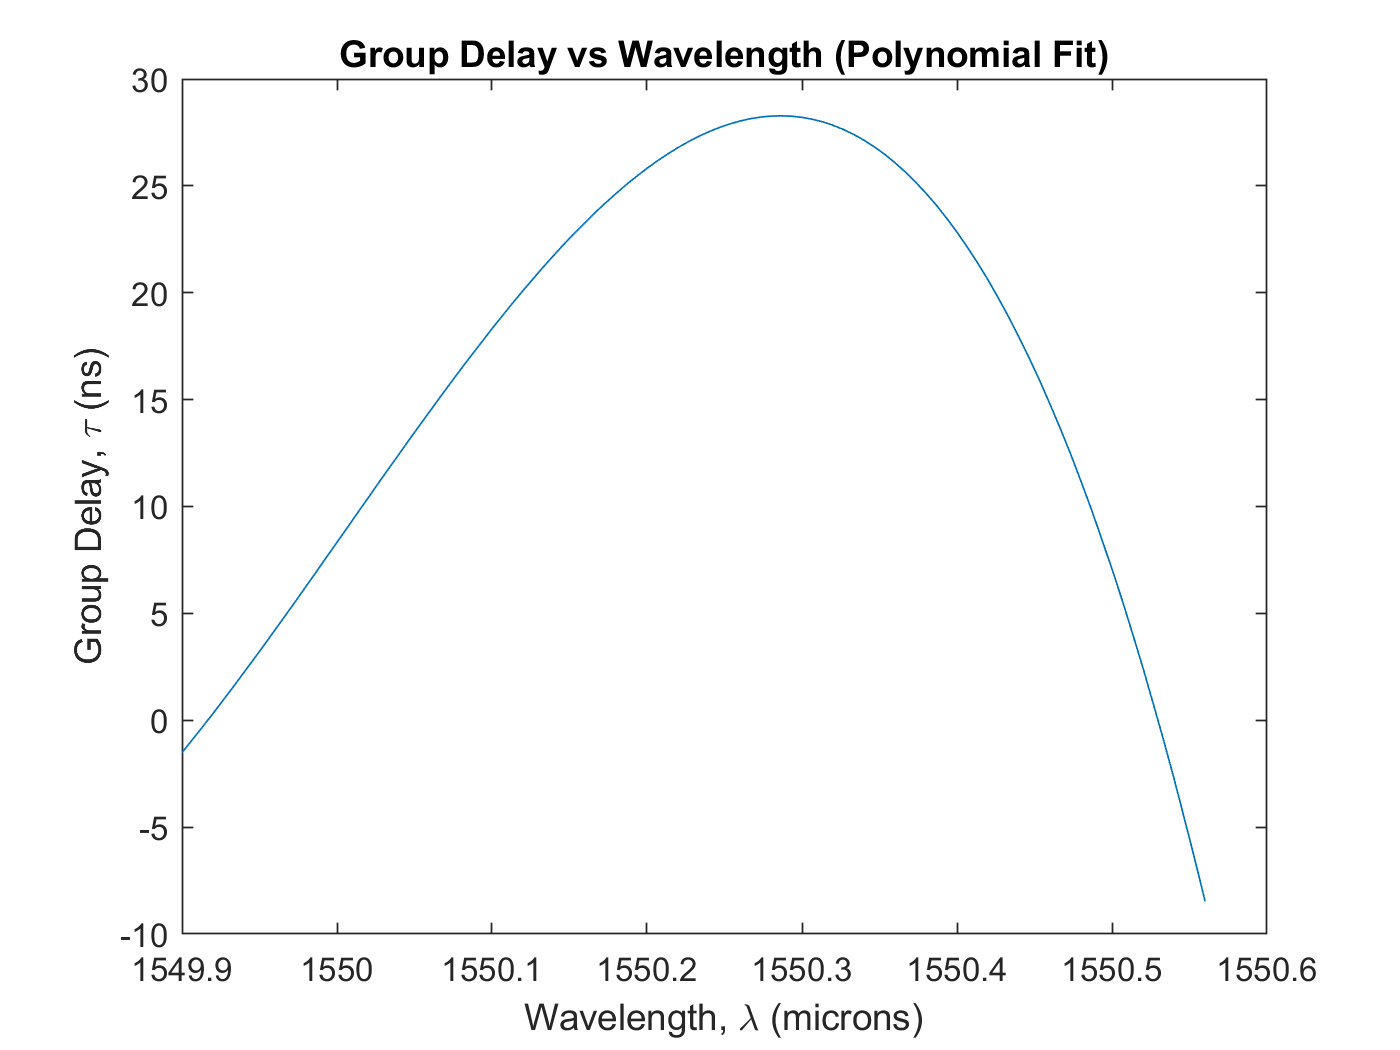

tau_fitlambda = polyval(coeffnew,x);
plot(x*10^9,tau_fitlambda*10^12)
xlabel('Wavelength, \lambda (microns)')
ylabel('Group Delay, \tau (ns)')
title('Group Delay vs Wavelength (Polynomial Fit)')

**c)**

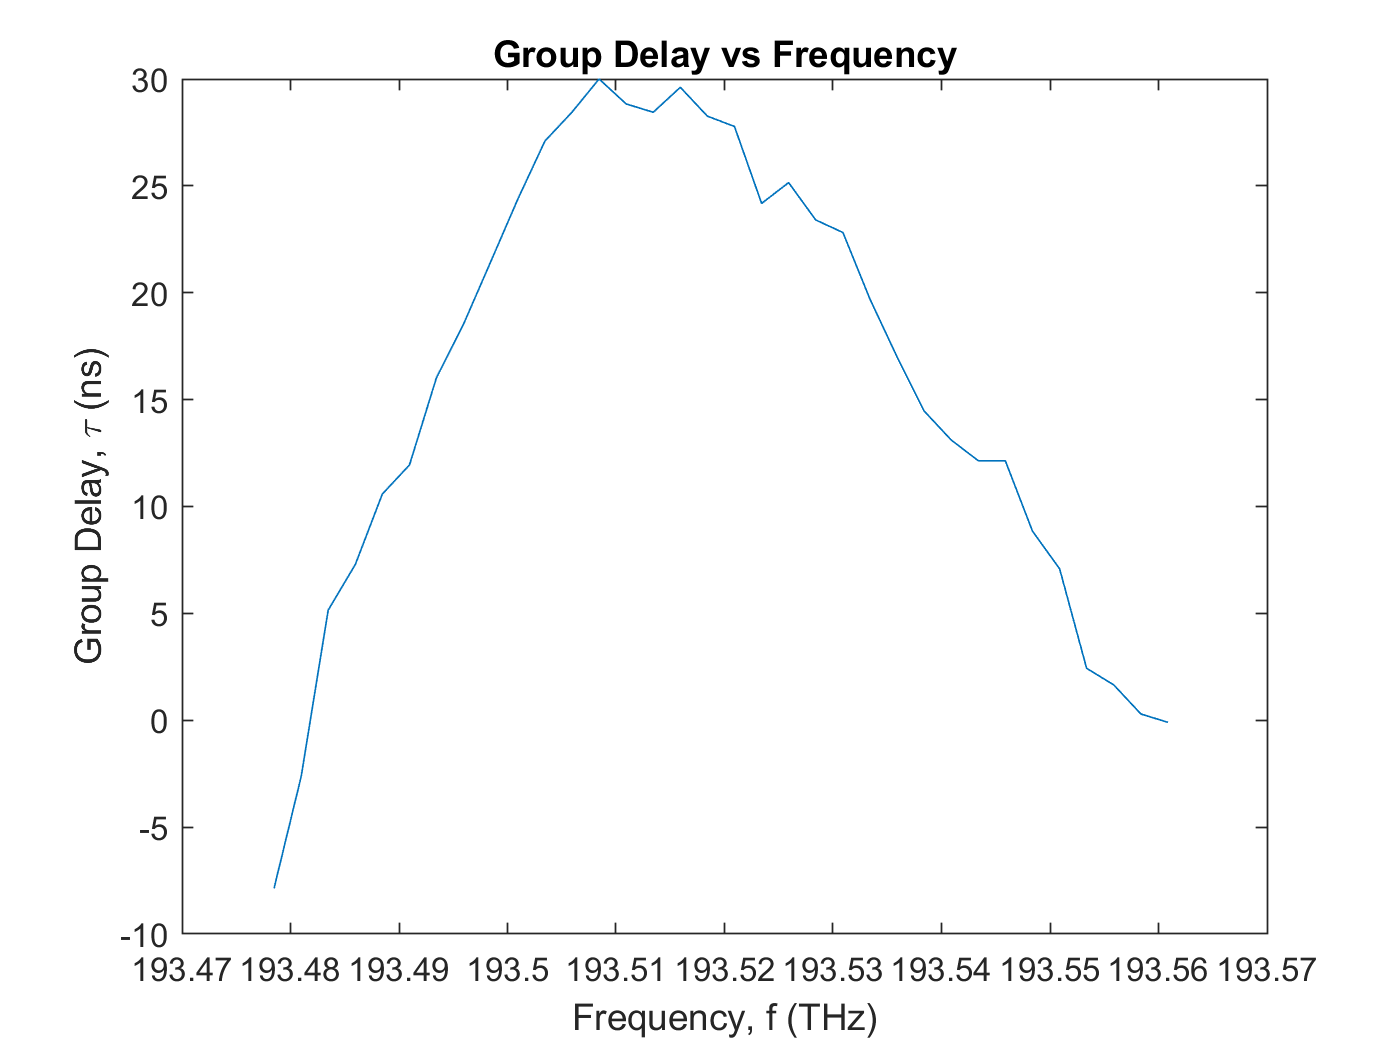

plot(omega_sweep./(2*pi)*10^-12,tau_sweep*10^12)
xlabel('Frequency, f (THz)')
ylabel('Group Delay, \tau (ns)')
title('Group Delay vs Frequency')

% Using polynomial fit determined previously
y = linspace(min(omega_sweep./(2*pi)),max(omega_sweep./(2*pi)));
coeffnew1 = polyfit(omega_sweep./(2*pi),tau_sweep,3);

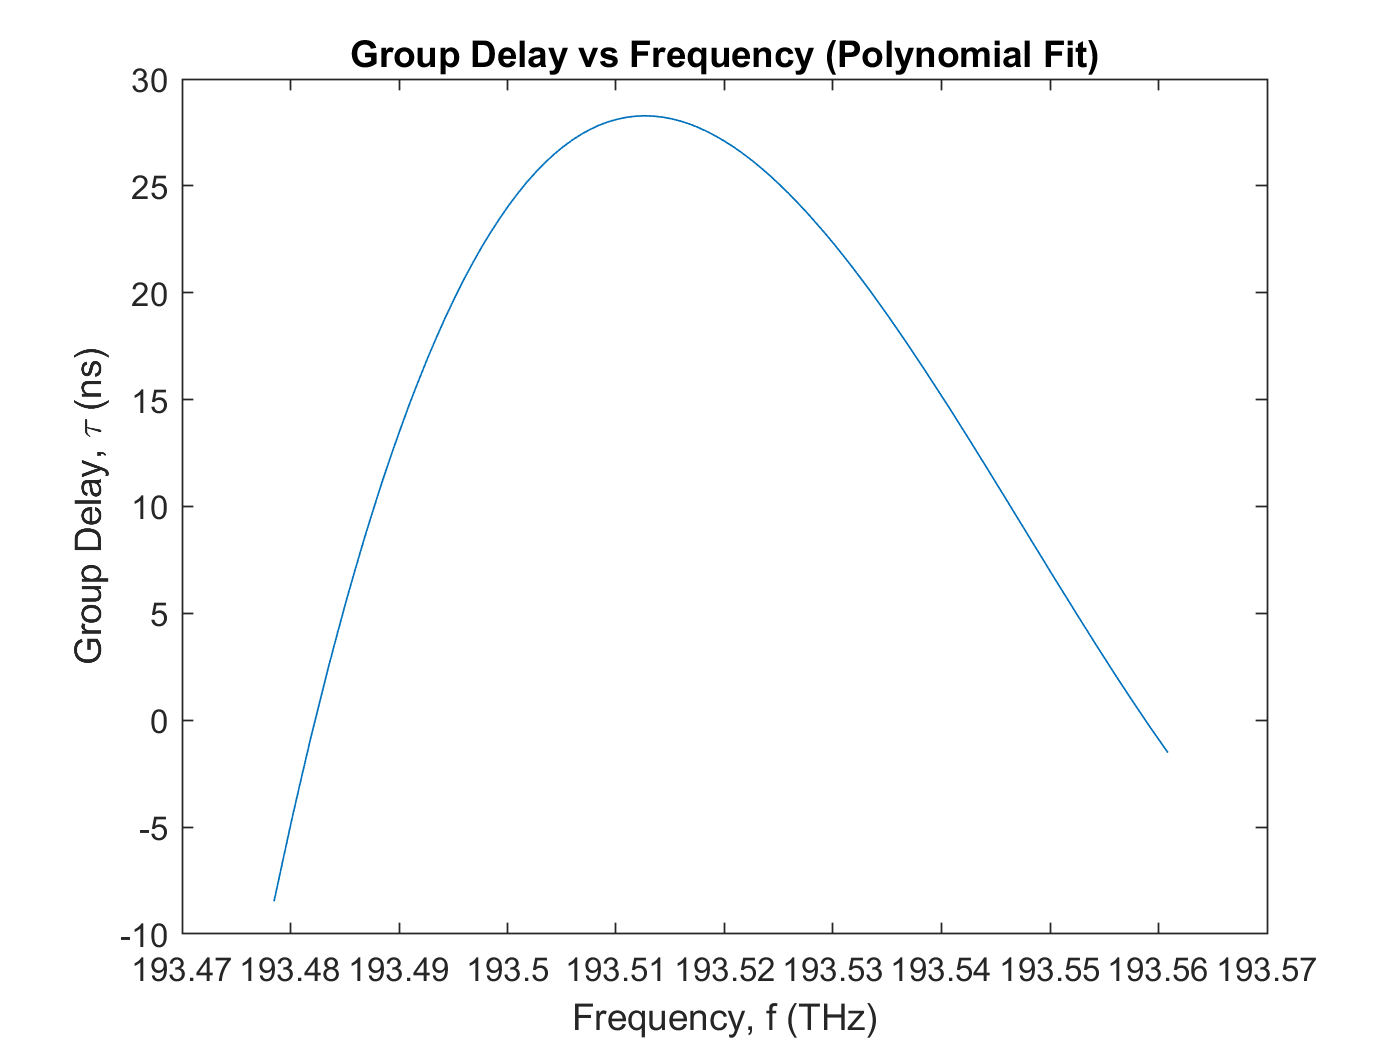

tau_fitFreq = polyval(coeffnew1,y);
plot(y*10^-12,tau_fitFreq*10^12)
xlabel('Frequency, f (THz)')
ylabel('Group Delay, \tau (ns)')
title('Group Delay vs Frequency (Polynomial Fit)')

**d) **

The intensity in the cavity is given by: 

$I=\frac{I_0 }{{\left(1-R\right)}^2 +4R{\mathrm{sin}}^2 \left(\beta L\right)}$, where $\beta =\beta \left(\omega \right)$ carries the frequency dependence of the cavity. We can utilize our polynomial fit to get an expression for this phase term

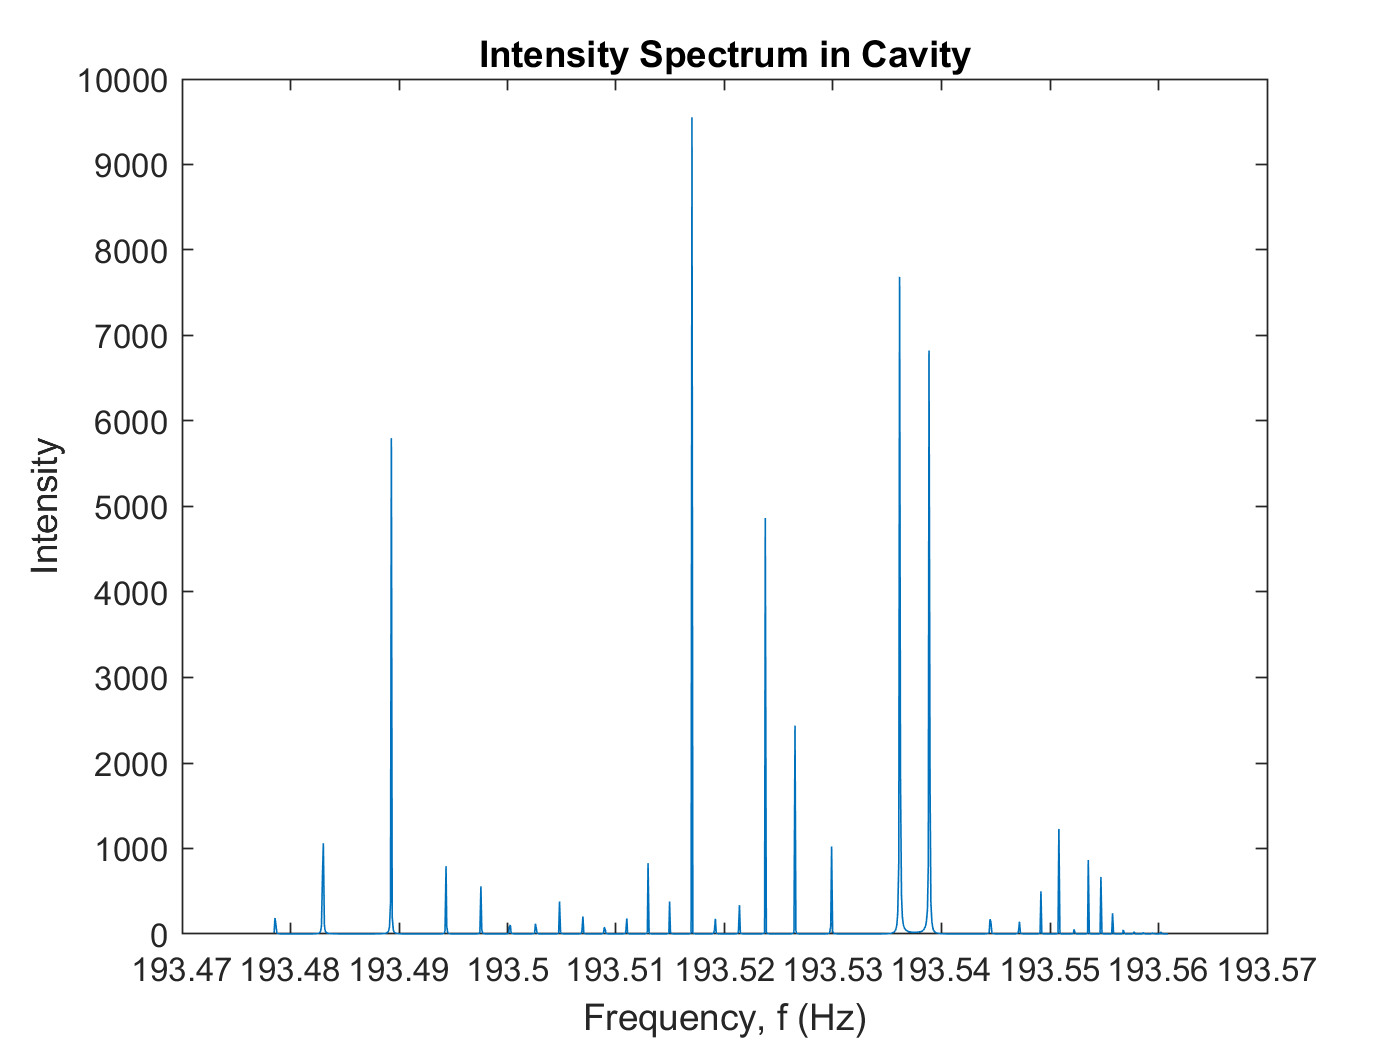

R = .99; % Reflectivity of the cavity is 99%
omega_sweep = linspace(min(omega_sweep),max(omega_sweep),1000);
%omega_sweep = interp1(lambda_sweep,omega_sweep,lambda_sweep);
beta = beta_0 + beta_1.*(omega_sweep-omega_mean) + (beta_2/2).*(omega_sweep-omega_mean).^2 + (beta_3/6).*(omega_sweep-omega_mean).^3;
I = 1./((1-R).^2 + 4*R*(sin(beta*L)).^2);
plot(omega_sweep./(2*pi)*10^-12,I)
xlabel('Frequency, f (Hz)')
ylabel('Intensity')
title('Intensity Spectrum in Cavity')

clc 
clear all

c = 3*10^8;

## Part 2: Group Delay Dispersion

**a) **

The refractive index versus wavelength data is downloaded from 'refractiveindex.info' using the 'readmatrix' function.  'Nvslambda' stores the wavelvength in column 1, and corresponding n and k in columns 2 and 3, respectively

Nvslambda = readmatrix('RefractiveIndexINFO.xlsx');
lambda_sweep = Nvslambda(:,1)*10^-6; % raw wavelength data (microns to m)
lambda_mean = mean(lambda_sweep);

**b) **

Converting each wavelength to angular frequency, $\omega$ is given by: 


$$\omega =2\pi \frac{c}{\lambda }$$


And refractive index to beta is given by: 

$\beta =n\left(\omega \right)\frac{\omega }{c}=\beta_0 +\beta_1 \left(\omega -\omega_0 \right)+\frac{\beta_2 }{2}{\left(\omega -\omega_0 \right)}^2 +\frac{1}{6}\beta_3 {\left(\omega -\omega_0 \right)}^3$, where $\beta_0 =2\pi \frac{n}{\lambda_0 }=n\frac{\omega }{c}=k_0$, $\beta_1 =\frac{1}{c}\left(n+\omega \frac{\textrm{dn}}{d\omega }\right)=\frac{n_g }{c}=\frac{1}{v_g }$,$\beta_2 =\frac{1}{c}\left(2\frac{\mathrm{dn}}{d\omega }+\omega \frac{d^2 n}{d\omega^2 }\right)=\frac{\omega }{c}\frac{d^2 n}{d\omega^2 }=\frac{\lambda^3 }{2\pi c^2 }\frac{d^2 n}{d\lambda^2 }$.  These constants will be determined from a polynomial fit of the wavevector vs angular frequence, or $\beta \;\mathrm{vs}\;\omega$ 

omega_sweep = 2*pi*c./lambda_sweep; % convert wavelength to ang. frequency 
omega_mean = mean(omega_sweep);
omega_new = (omega_sweep-omega_mean);
n_sweep = Nvslambda(:,2); % Real part of N is imported, inherently a function of angular frequency through the wavelength
n_mean = mean(n_sweep);
n_new = (n_sweep-n_mean);
n_omega = interp1(2*pi*c./lambda_sweep,n_sweep,omega_sweep);

A polynomial fit of the wavevector $\beta$, and angular frequency, $\omega$ will give us the following expression: $\beta_0 +\beta_1 \left(\omega -\omega_0 \right)+\frac{\beta_2 }{2}{\left(\omega -\omega_0 \right)}^2 +\frac{1}{6}\beta_3 {\left(\omega -\omega_0 \right)}^3$, where the coefficients are more explicitly defined as: 

$\beta_0 =2\pi \frac{n}{\lambda_0 }=n\frac{\omega }{c}=k_0$,  $\beta_1 =\frac{1}{c}\left(n+\omega \frac{\mathrm{dn}}{d\omega }\right)=\frac{n_g }{c}=\frac{1}{v_g }$,  $\beta_2 =\frac{1}{c}\left(2\frac{\mathrm{dn}}{d\omega }+\omega \frac{d^2 n}{d\omega^2 }\right)=\frac{\omega }{c}\frac{d^2 n}{d\omega^2 }=\frac{\lambda^3 }{2\pi c^2 }\frac{d^2 n}{d\lambda^2 }$

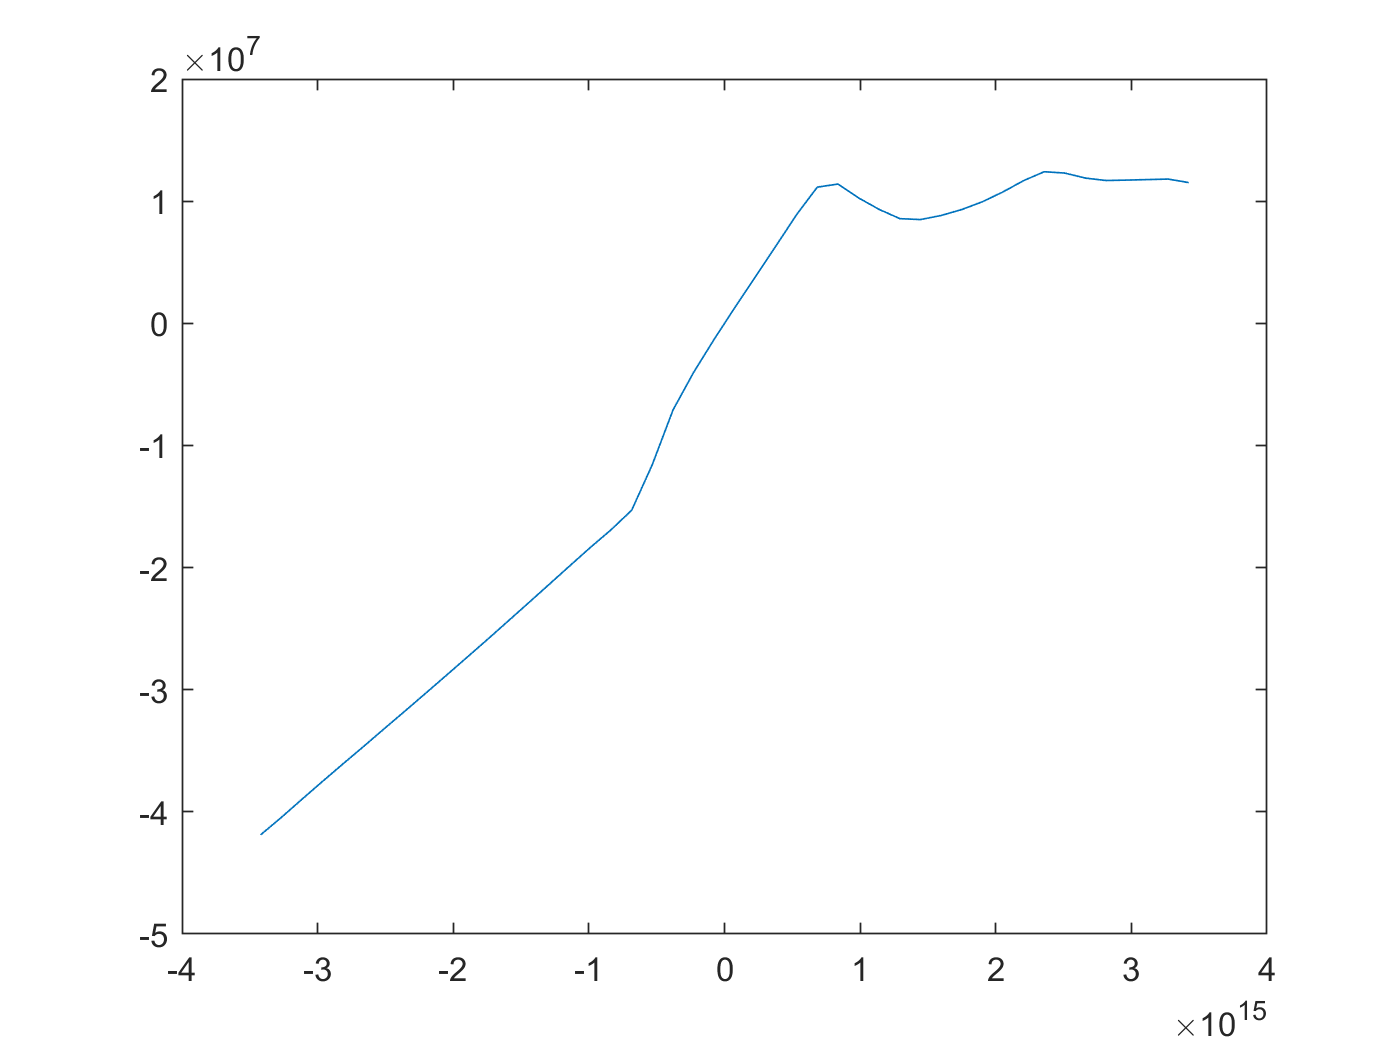

beta_omega = n_omega.*(omega_new)./c; % beta as function of ang. freq. through the refractive index
plot(omega_new,beta_omega)

coeff = polyfit(omega_new,beta_omega,3)

coeff = 	1.0e+06 *

   -0.0000   -0.0000    0.0000   -2.5517


%x = linspace(
beta_0 = coeff(4)

beta_0 = -2.5517e+06

beta_1 = coeff(3)

beta_1 = 1.2131e-08

beta_2 = coeff(2)*2

beta_2 = -2.4268e-24

beta_3 = coeff(1)*6

beta_3 = -2.5108e-39

**c)**

The dispersion coefficient, D, as hinted has units of time vs incremental wavelength.  If $\tau$ is the group delay, then D is given by: 


$$D=\frac{d\tau }{d\lambda }=\frac{{d\beta }_1 }{d\lambda }=-\frac{2\pi c}{\lambda^2 }\beta_2 =-\frac{\lambda }{c}\frac{d^2 n}{d\lambda^2 }$$


D = -beta_2*(2*pi*c)/(lambda_mean^2) % The dispersion parameter, D

D = 0.0309